# COCOAN 101: Lecture 13 - Visualization - Connectivity and Network

## Basic Setting

basedir = '/Users/jaejoonglee/Dropbox/Presentations/Lecture/2021_cocoan101'; % Change this path
load(fullfile(basedir, 'Cocoan101_L13_data_ROI_meants.mat'), '*_roi_meants');
atlas_img = fmri_data(which('Fan_et_al_atlas_r279_MNI.nii'));

Using default mask: /Users/jaejoonglee/github/canlab/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 971812 bytes
Loading image number:     1
경과 시간은 0.512960초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 280  Bit rate: 8.13 bits


load(which('cluster_Fan_Net_r279.mat'));
net_val = cluster_Fan_Net.dat(:,13);
net_cols = cluster_Fan_Net.ten_network_col;
net_lat = cluster_Fan_Net.dat(:,7);
net_reg = cluster_Fan_Net.r_2mm;
net_regname = cluster_Fan_Net.names_short;
load(fullfile(basedir, 'Cocoan101_L13_colormap.mat'));

CAPS_avg_r = cellfun(@corrcoef, CAPS_roi_meants, 'UniformOutput', false);
CAPS_avg_r = mean(cat(3, CAPS_avg_r{:}), 3);

thr_lv = [0.01 0.05 0.1];
for i = 1:numel(thr_lv)
    CAPS_thr_r{i} = CAPS_avg_r .* double(abs(CAPS_avg_r) > prctile(CAPS_avg_r(:), 100*(1-thr_lv(i))));
end

## Correlation matrix: 'vis_corr.m'

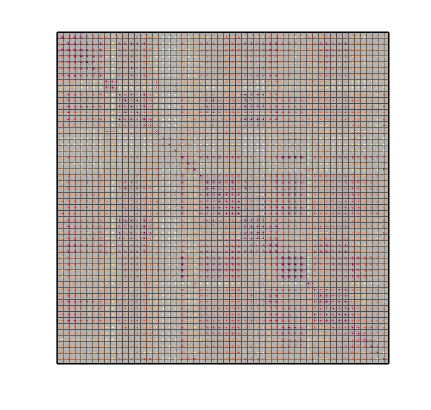

vis_corr(CAPS_avg_r); drawnow; close all;

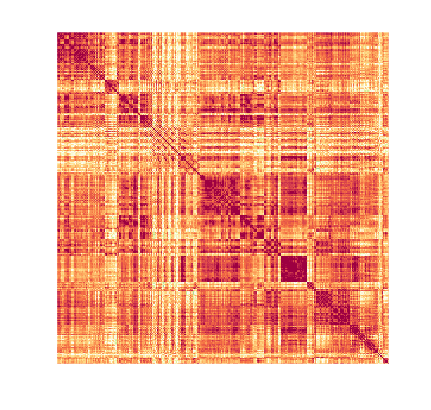

vis_corr(CAPS_avg_r, 'nolines'); drawnow; close all;

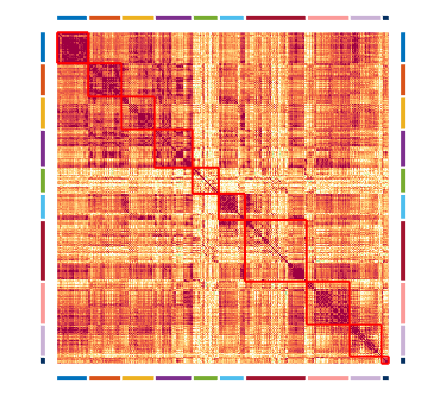

vis_corr(CAPS_avg_r, 'nolines', 'group', net_val, 'group_color', net_cols); drawnow; close all;

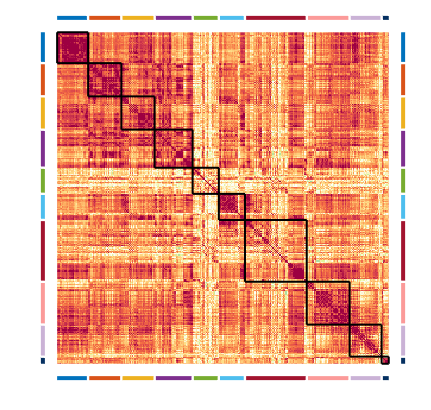

vis_corr(CAPS_avg_r, 'nolines', 'group', net_val, 'group_color', net_cols, 'group_linewidth', 2, 'group_linecolor', 'k'); drawnow; close all;

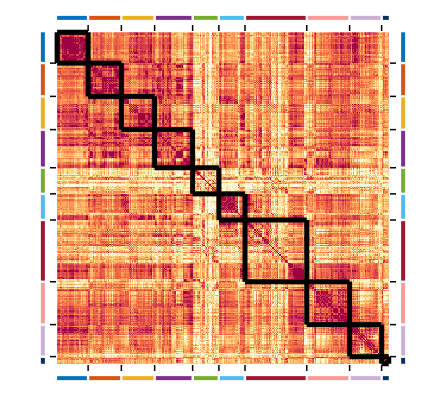

vis_corr(CAPS_avg_r, 'nolines', 'group', net_val, 'group_color', net_cols, 'group_linewidth', 5, 'group_linecolor', 'k', ...
    'group_tick', 'group_tickstyle', 'edge', 'group_tickwidth', 1.5, 'group_ticklength', 5, 'group_tickoffset', 1); drawnow; close all;

vis_corr(CAPS_avg_r, 'nolines', 'group', net_val, 'group_color', net_cols, 'group_linewidth', 5, 'group_linecolor', 'k', ...
    'group_tick', 'group_tickstyle', 'edge', 'group_tickwidth', 1.5, 'group_ticklength', 5, 'group_tickoffset', 1, ...
    'triangle', 'no_triangle_line'); drawnow; close all;

vis_corr(CAPS_avg_r, 'nolines', 'group', net_val, 'group_color', net_cols, 'group_linewidth', 5, 'group_linecolor', 'k', ...
    'group_tick', 'group_tickstyle', 'edge', 'group_tickwidth', 1.5, 'group_ticklength', 5, 'group_tickoffset', 1, ...
    'triangle', 'no_triangle_line', 'smooth'); drawnow; close all;

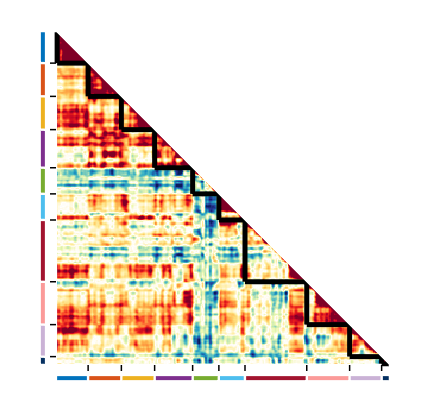

vis_corr(CAPS_avg_r, 'nolines', 'group', net_val, 'group_color', net_cols, 'group_linewidth', 5, 'group_linecolor', 'k', ...
    'group_tick', 'group_tickstyle', 'edge', 'group_tickwidth', 1.5, 'group_ticklength', 5, 'group_tickoffset', 1, ...
    'triangle', 'no_triangle_line', 'smooth', 'colors', col_diff_map1, 'clim', [0 0.6]); drawnow; close all;

## Connectivity circos plot: 'circos_multilayer.m'

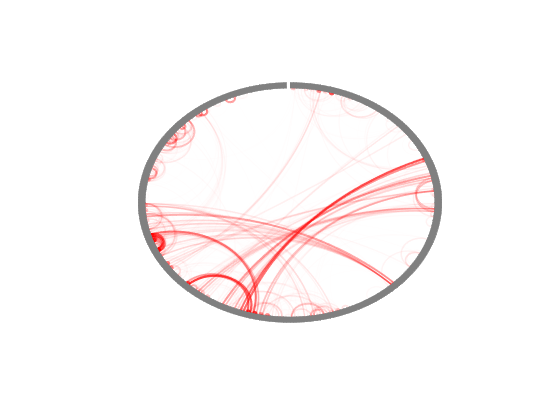

zto_fx = @(x) (x - min(x)) ./ (max(x) - min(x));
circos_multilayer(CAPS_thr_r{2}); drawnow; close all;

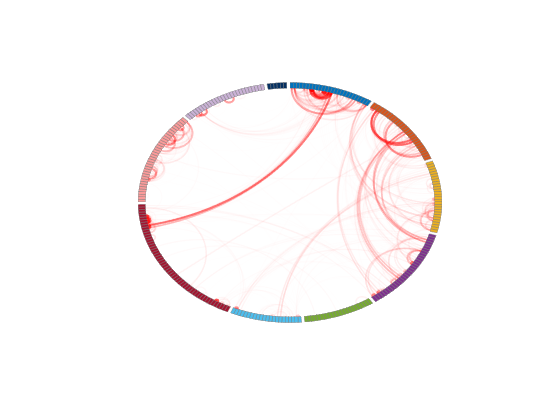

circos_multilayer(CAPS_thr_r{2}, 'group', net_val, 'group_color', net_cols); drawnow; close all;

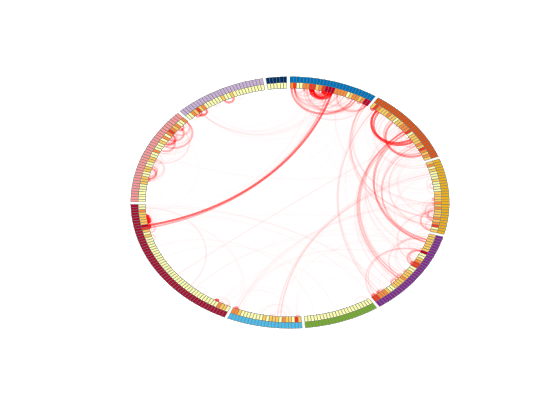

circos_multilayer(CAPS_thr_r{2}, 'group', net_val, 'group_color', net_cols, ...
    'add_layer', {'layer', zto_fx(mean(CAPS_thr_r{2})), 'color', 'degree'}); drawnow; close all;

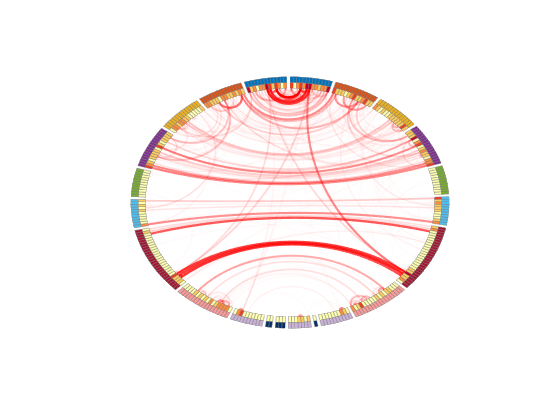

circos_multilayer(CAPS_thr_r{2}, 'group', net_val, 'group_color', net_cols, ...
    'add_layer', {'layer', zto_fx(mean(CAPS_thr_r{2})), 'color', 'degree'}, 'laterality', net_lat); drawnow; close all;

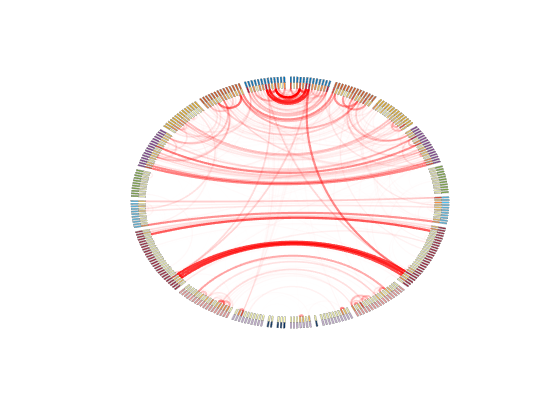

circos_multilayer(CAPS_thr_r{2}, 'group', net_val, 'group_color', net_cols, ...
    'add_layer', {'layer', zto_fx(mean(CAPS_thr_r{2})), 'color', 'degree'}, 'laterality', net_lat, ...
    'length_ratio', [1 1 2]); drawnow; close all;

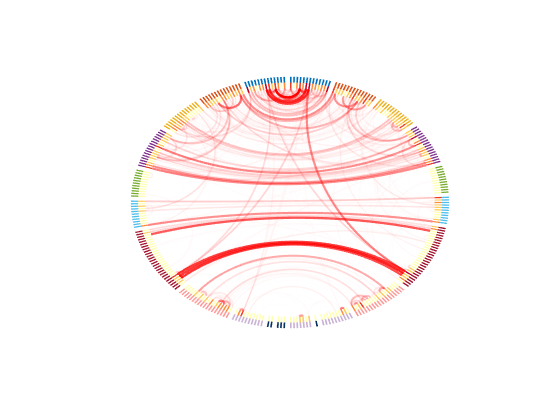

circos_multilayer(CAPS_thr_r{2}, 'group', net_val, 'group_color', net_cols, ...
    'add_layer', {'layer', zto_fx(mean(CAPS_thr_r{2})), 'color', 'degree'}, 'laterality', net_lat, ...
    'length_ratio', [1 1 2], 'patch_edge_alpha', 0); drawnow; close all;

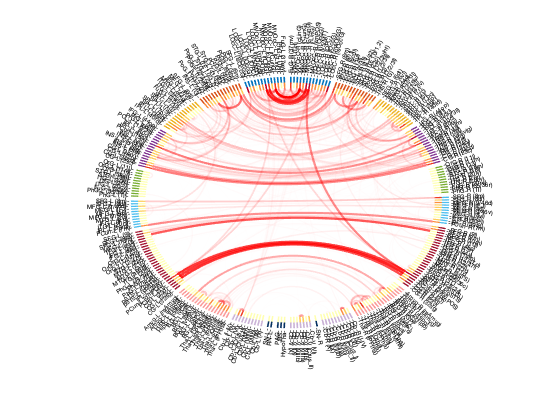

circos_multilayer(CAPS_thr_r{2}, 'group', net_val, 'group_color', net_cols, ...
    'add_layer', {'layer', zto_fx(mean(CAPS_thr_r{2})), 'color', 'degree'}, 'laterality', net_lat, ...
    'length_ratio', [1 1 2], 'patch_edge_alpha', 0, 'region_names', net_regname); drawnow; close all;

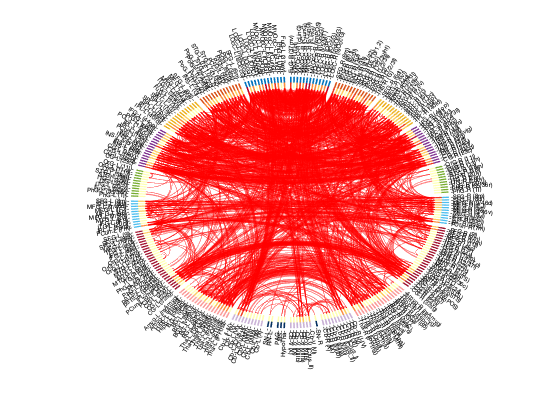

circos_multilayer(CAPS_thr_r{2}, 'group', net_val, 'group_color', net_cols, ...
    'add_layer', {'layer', zto_fx(mean(CAPS_thr_r{2})), 'color', 'degree'}, 'laterality', net_lat, ...
    'length_ratio', [1 1 2], 'patch_edge_alpha', 0, 'region_names', net_regname, 'alpha_fun', @(x) ones(size(x))*0.5); drawnow; close all;

## Glass brain: 'glass_brain_network.m'

basecolor =     0.5000    0.5000    0.5000


Main color vertices: Coords is empty. Nothing to plot.


 Running color change.


basecolor =     0.5000    0.5000    0.5000


Main color vertices: Coords is empty. Nothing to plot.


 Running color change.


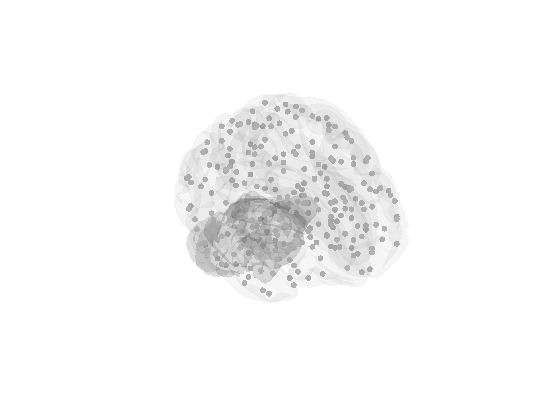

out = glass_brain_network(net_reg); drawnow; close all;

basecolor =     0.5000    0.5000    0.5000


Main color vertices: Coords is empty. Nothing to plot.


 Running color change.


basecolor =     0.5000    0.5000    0.5000


Main color vertices: Coords is empty. Nothing to plot.


 Running color change.


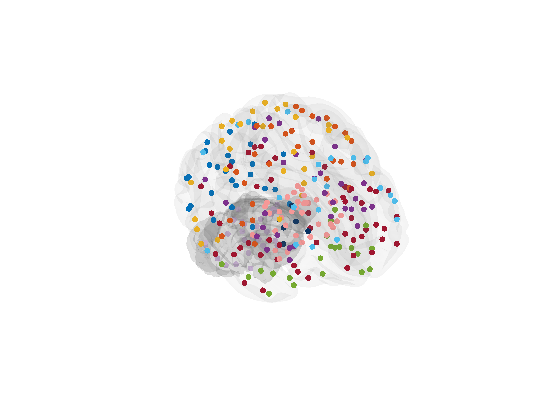

out = glass_brain_network(net_reg, 'group', net_val, 'colors', net_cols); drawnow; close all;

basecolor =     0.5000    0.5000    0.5000


Main color vertices: Coords is empty. Nothing to plot.


 Running color change.


basecolor =     0.5000    0.5000    0.5000


Main color vertices: Coords is empty. Nothing to plot.


 Running color change.


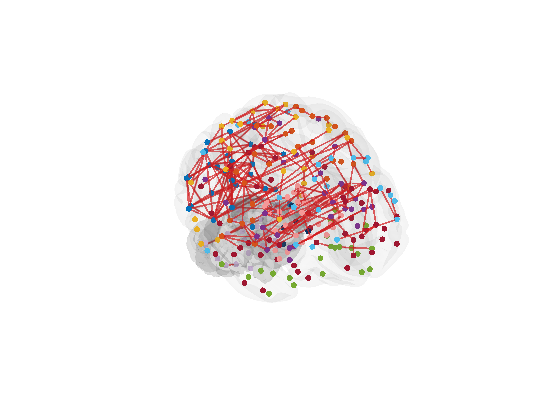

out = glass_brain_network(net_reg, 'group', net_val, 'colors', net_cols, ...
    'edge_weights', CAPS_thr_r{1}, 'edge_alpha', 0.7, 'norm_factor', 1.5); drawnow; close all;

basecolor =     0.5000    0.5000    0.5000


Main color vertices: Coords is empty. Nothing to plot.


 Running color change.


basecolor =     0.5000    0.5000    0.5000


Main color vertices: Coords is empty. Nothing to plot.


 Running color change.


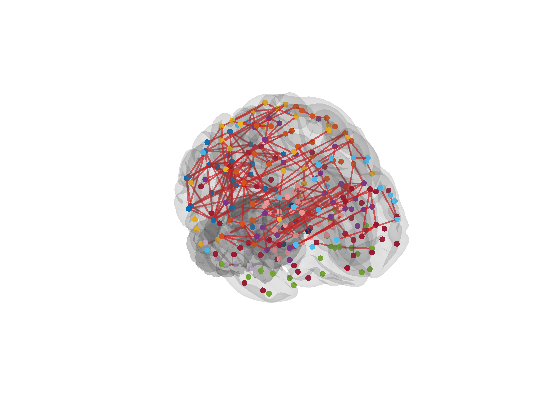

out = glass_brain_network(net_reg, 'group', net_val, 'colors', net_cols, ...
    'edge_weights', CAPS_thr_r{1}, 'edge_alpha', 0.7, 'norm_factor', 1.5, 'cortex_alpha', .1, 'cerebellum_alpha', .2); drawnow; close all;

## Network plot: 'vis_network.m'

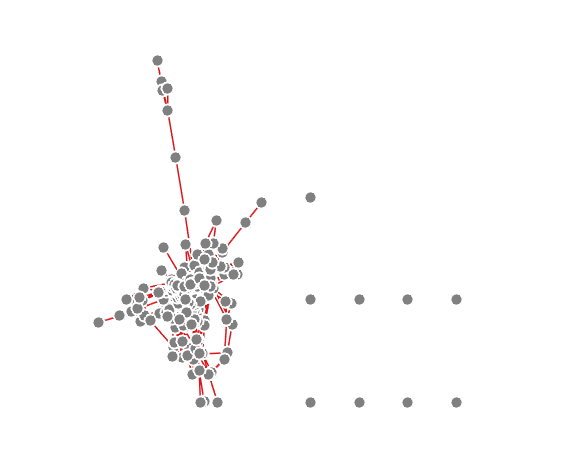

h = vis_network(CAPS_thr_r{3}); drawnow; close all;

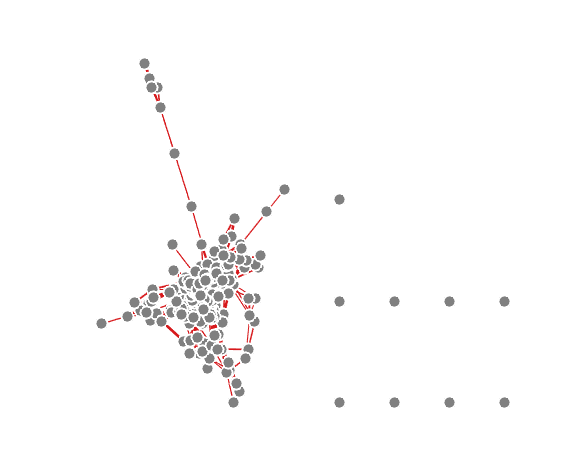

h = vis_network(CAPS_thr_r{3}, 'weighted'); drawnow; close all;

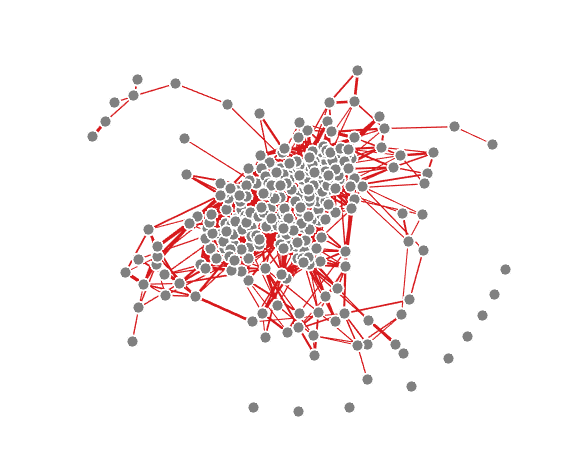

h = vis_network(CAPS_thr_r{3}, 'weighted', 'gravity'); drawnow; close all;

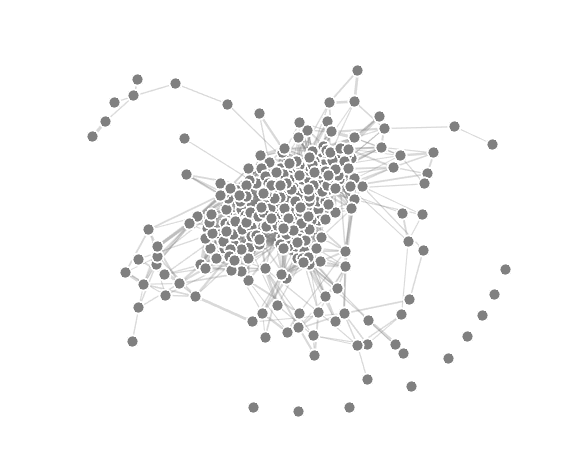

h = vis_network(CAPS_thr_r{3}, 'weighted', 'gravity', 'line_pos_color', [0.5 0.5 0.5 0.3]); drawnow; close all;

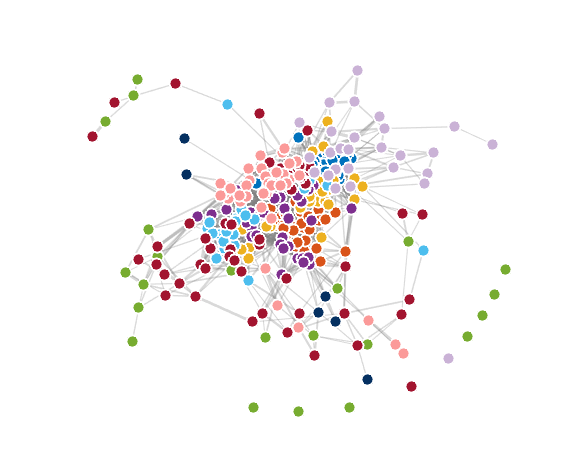

h = vis_network(CAPS_thr_r{3}, 'weighted', 'gravity', 'line_pos_color', [0.5 0.5 0.5 0.3], ...
    'group', net_val, 'groupcolor', net_cols); drawnow; close all;

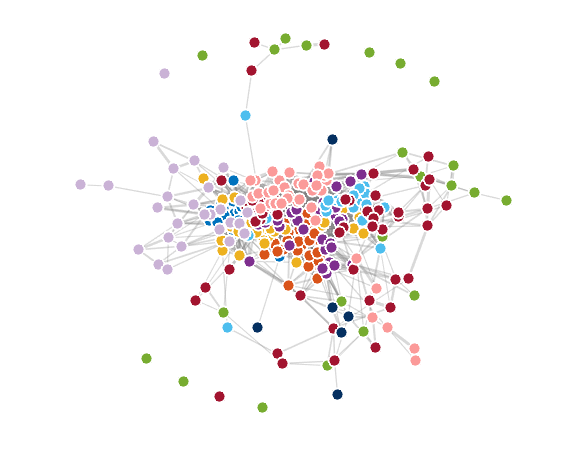

h = vis_network(CAPS_thr_r{3}, 'weighted', 'gravity', 'line_pos_color', [0.5 0.5 0.5 0.3], ...
    'group', net_val, 'groupcolor', net_cols, 'xystart', net_reg); drawnow; close all;